## **Simulation for Active Structures -- A Living Textbook**

**by Yi Zhu (PhD)**

clear all; 
close all; 
clc;

***Please add "00_SourceCode_Elements" and "00_SourceCode_Solver" into path before running the code***

### **Section 09 - Example 04 - Laoding of Scissor Mechanism**

In the previous example, we showed how to simulate the deployment a scissor mechanism. Here, we want to see how we can capture the load-carrying behavior of the same system. 

 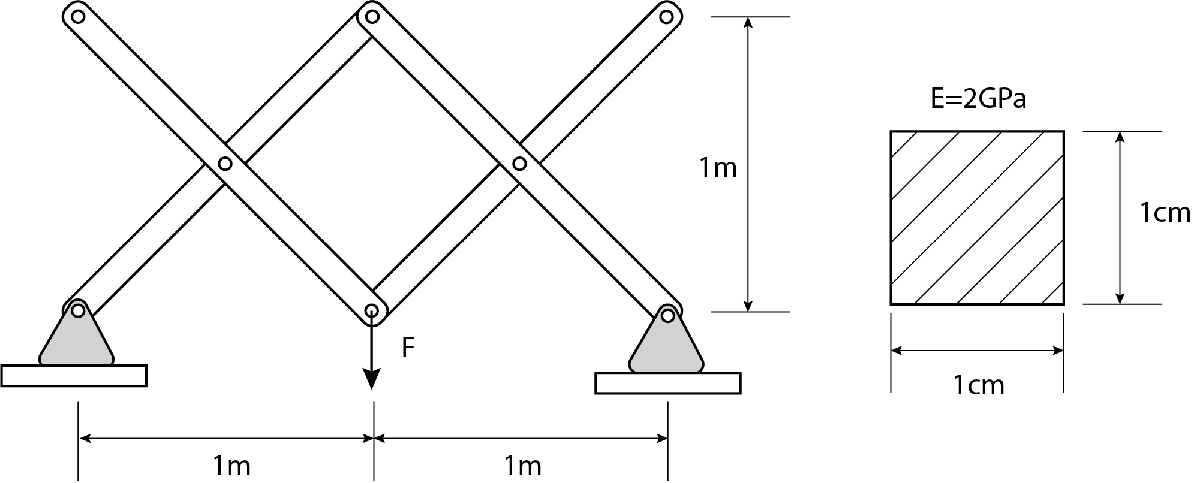

The above figure shows the loaing set up. Please do notice that the support information is changed. Now, both ends are fixed support - this will turn the mechanism into a structure. 

The set up of the simulation is mostly the same as the previous one so we will skip uncessary descriptions. 

clear all;
clc;
close all;

%% Initialize the truss
% Define the nodes
H=1; % Height of the truss
L=1; % Length of each span
barA=0.0001; % cross section area (m^2)
barE=2*10^9; % Youngs' modulus (Pa)

% We will also solve for the bending stiffness of the frame
I=1/12*0.01^4;
% When using four segment to represent a frame, 
% three rotational springs are used
% Using Larry Howell's pseudo rigid body model
% We can convert the bending stiffness to spring stiffness
barL=sqrt(H^2+L^2);
kspr=3*barE*I/barL;

Define all the objects for the elements we need to use

% Define the node object
node=Elements_Nodes;
% Create the bar object
bar=CD_Elements_Bars;
% Create the 3-node rot spring
rot_spr_3N=CD_Elements_RotSprings_3N;

% Create tje truss Assembly
assembly=Assembly_2D_Mechanism;
% This assembly has a node object and a bar object
assembly.node=node;
assembly.bar=bar;
assembly.rot_spr_3N=rot_spr_3N;

Here, the nodal coordinates of this example is the same as Example 02.

%% Define the nodal coordinates
% Here we need to set up the nodal coordinates of our truss
node.coordinates_mat=[0*L 0 0; 
                      1*L 0 0;
                      2*L 0 0; % Node 3
                      0*L 0 H;
                      1*L 0 H; 
                      2*L 0 H; % Node 6
                      0.5*L 0 0.5*H; 
                      1.5*L 0 0.5*H; % Node 8
                      0.25*L 0 0.25*H;
                      0.75*L 0 0.25*H;
                      1.25*L 0 0.25*H;
                      1.75*L 0 0.25*H; % Node 12
                      0.25*L 0 0.75*H;
                      0.75*L 0 0.75*H;
                      1.25*L 0 0.75*H;
                      1.75*L 0 0.75*H; % Node 16
                      ];

We can plot the node for inspection.

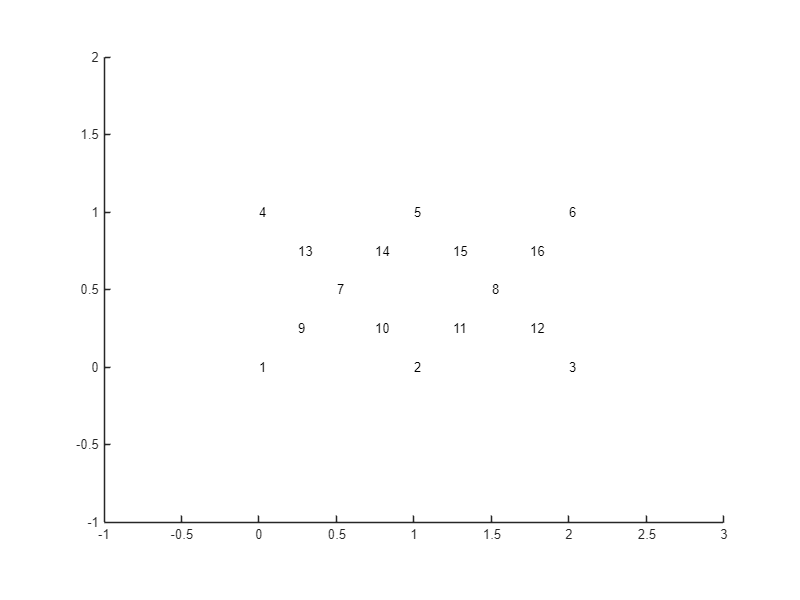

% Set up the plotting function for inspection
plots=Plot_2D_Mechanism();
plots.assembly=assembly;
% We will plot for the 2D mechnism assembly

plots.displayRange=[-1;3;-1;1;-1;2]; 
% Range of the plot
plots.viewAngle1=0;
plots.viewAngle2=0;
% Change the viewing angle

% Plot the nodal coordinates for inspection
plots.Plot_Shape_Node_Number()

We will continue to defing the bar and rotational springs. Please note that this process is also the same as Example 02.

% Define how bars are connected
% First we do the horizontal truss (bars)
bar.node_ij_mat=[1,9;
                 7,9;
                 7,14;
                 14,5; % 4 bars
                 4,13;
                 13,7;
                 7,10;
                 10,2; % 8 bars
                 2,11;
                 11,8;
                 8,16;
                 16,6; % 12 bars
                 5,15;
                 15,8;
                 8,12;
                 12,3;]; % 16 bars

% Define the area of the bars
% We have a total of 16 bars
bar.A_vec=barA*ones(16,1);
bar.E_vec=barE*ones(16,1);

Let's first plot the bar elements to see if everything looks good. 

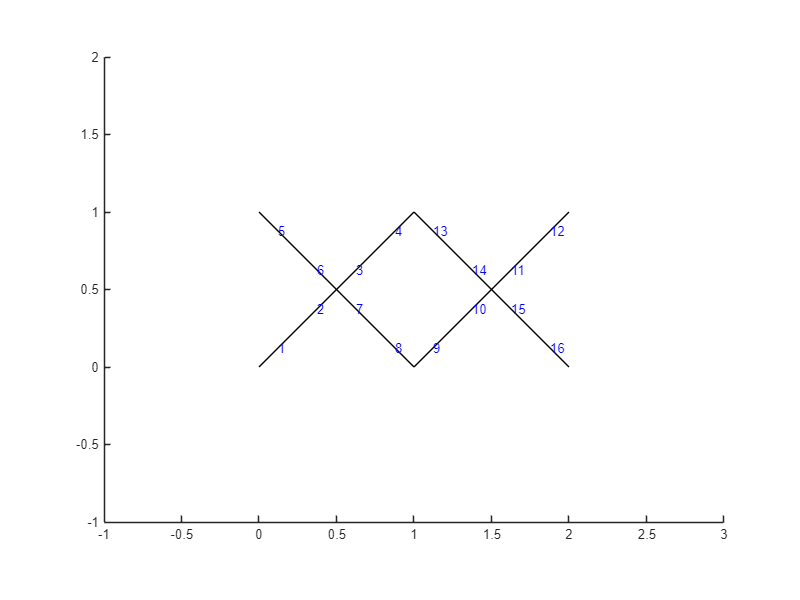

% Initialize the entire assembly 
assembly.Initialize_Assembly();
% Set up the 
plots.Plot_Shape_Bar_Number()

% Define how rotational springs are connected
rot_spr_3N.node_ijk_mat=[1 9 7;
                         9 7 14;
                         7 14 5; % 3 springs
                         4 13 7; 
                         13 7 10; 
                         7 10 2; % 6 springs
                         2 11 8; 
                         11 8 16; 
                         8 16 6; % 9 springs
                         5 15 8;  
                         15 8 12; 
                         8 12 3;]; % 12 springs

Here, we add the #13 spring to control the deployment. 

% We add another #13 spring to control the deployment
rot_spr_3N.node_ijk_mat=[rot_spr_3N.node_ijk_mat;
                         9 7 13];

We next defing the other properties of rotational springs and plot the springs.

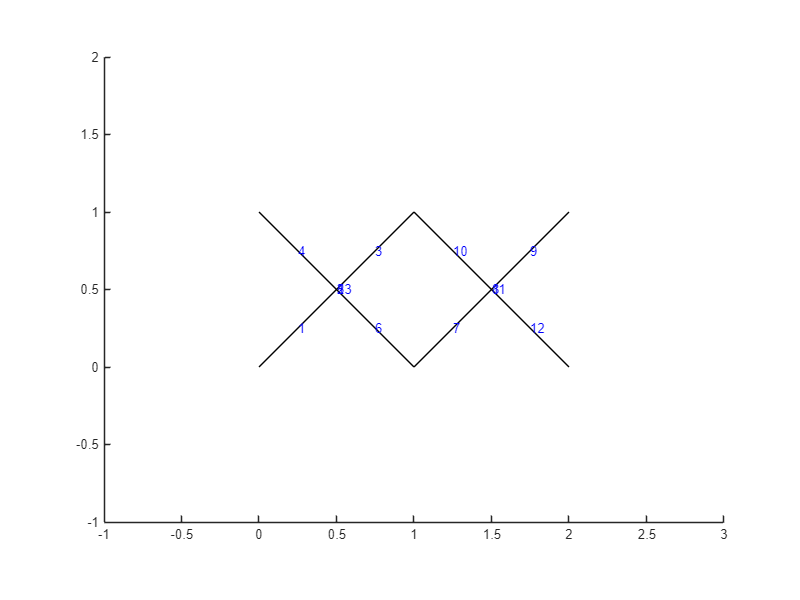

% Define rotational stiffness
rot_spr_3N.rot_spr_K_vec=kspr*ones(13,1);
% Initialize the entire assembly again for the new rot-spring
assembly.Initialize_Assembly();
% Plot the rotational spring number
plots.Plot_Shape_Spr_Number

Here, because we want to study the loading behavior, we need the "NR_Loading" solver. Please note that the support information is not the same as the Example 02. I encourage you to compare them to get a better understanding of the support definition. 

%% Set up the loading solver
nr=Solver_NR_Loading;
nr.assembly=assembly;
nr.supp=[1,1,1,1;
         2,0,1,0;
         3,1,1,1;
         4,0,1,0;
         5,0,1,0;
         6,0,1,0;
         7,0,1,0;
         8,0,1,0;
         9,0,1,0;
         10,0,1,0;
         11,0,1,0;
         12,0,1,0;
         13,0,1,0;
         14,0,1,0;
         15,0,1,0;
         16,0,1,0;];

For the load, we put a -1 N load in the Z direction at node 2. This is at the mid span of the scissor mechanism and is just like what we want to match the first figure. 

% Set up the load
nr.load=[2,0,0,-0.2];

We will compute the deployment in 5-steps. Each step, we allow a maximum of 30 iterations to find the equilibrium using the Newton's method.

% Set up the total loading step
nr.increStep=5;
% Set up the maximum iteration
nr.iterMax=30;
% Set up the tolorence
nr.tol=10^-6;

Now that everything is creatd, we can ask the program to find the loading deformation history Uhis for us. This is done by asking the solver object "nr" to perform the "Solve()" function. 

% Solve for the deformation history
Uhis=nr.Solve();

Loading Analysis StartIcrement = 1
    Iteration = 1, R = 2.833525e-02
    Iteration = 2, R = 2.829322e-04
    Iteration = 3, R = 4.784108e-05
    Iteration = 4, R = 1.284126e-08
Icrement = 2
    Iteration = 1, R = 2.865385e-02
    Iteration = 2, R = 2.927855e-04
    Iteration = 3, R = 4.807351e-05
    Iteration = 4, R = 2.362970e-08
Icrement = 3
    Iteration = 1, R = 2.909361e-02
    Iteration = 2, R = 2.847173e-04
    Iteration = 3, R = 7.854853e-05
    Iteration = 4, R = 1.724709e-07
Icrement = 4
    Iteration = 1, R = 2.951407e-02
    Iteration = 2, R = 2.881119e-04
    Iteration = 3, R = 1.225724e-04
    Iteration = 4, R = 5.971797e-07
Icrement = 5
    Iteration = 1, R = 2.932259e-02
    Iteration = 2, R = 3.657143e-04
    Iteration = 3, R = 3.794487e-04
    Iteration = 4, R = 8.266396e-07


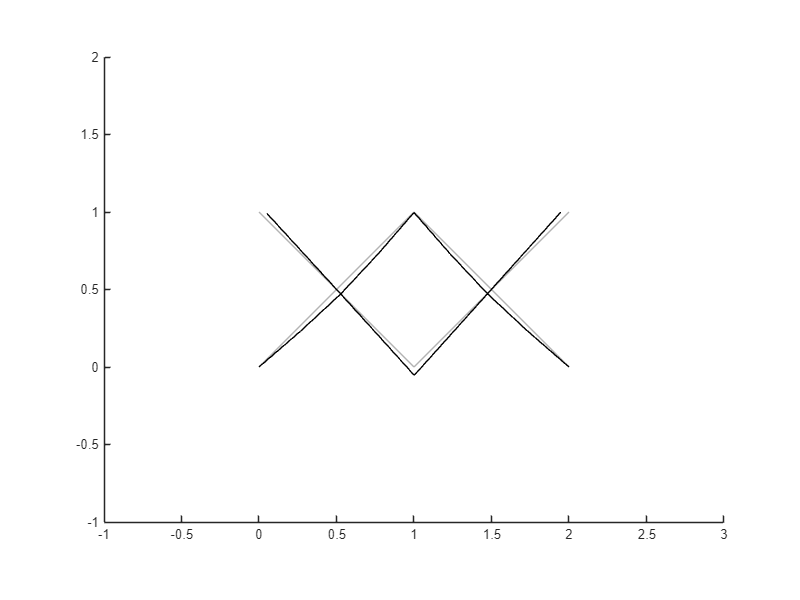

% Plot the deformed shape
plots.Plot_Deformed_Shape(squeeze(Uhis(end,:,:)),zeros(16,3));

Looking fine. 

Now, let's do the fun thing, we want to remove the first load, change the configuration, deploy this scissor mechanism bridge longer, and reapply the load. 

% Reinitialize will wipe out the previous loading information
assembly.Initialize_Assembly;

% Change the configuration with applied loading
nr_reconfig=Solver_NR_Folding_3N;
nr_reconfig.assembly=assembly;
nr_reconfig.supp=[1,1,1,1;
         2,0,1,1;
         3,0,1,1;
         4,0,1,0;
         5,0,1,0;
         6,0,1,0;
         7,0,1,0;
         8,0,1,0;
         9,0,1,0;
         10,0,1,0;
         11,0,1,0;
         12,0,1,0;
         13,0,1,0;
         14,0,1,0;
         15,0,1,0;
         16,0,1,0;];

% Set up the load
nr_reconfig.target_rot=rot_spr_3N.theta_current_vec;
nr_reconfig.target_rot(13)=pi*0.1;

% Set up the total loading step
nr_reconfig.increStep=60;
% Set up the maximum iteration
nr_reconfig.iterMax=30;
% Set up the tolorence
nr_reconfig.tol=10^-6;

% Solve for the deformation history
Uhis=nr_reconfig.Solve();

Self Assemble Analysis StartIcrement = 1
	Iteration = 1, R = 4.188798e-01 
	Iteration = 2, R = 2.364796e+01 
	Iteration = 3, R = 3.215427e-04 
	Iteration = 4, R = 3.834542e-03 
	Iteration = 5, R = 3.839601e-07 
Icrement = 2
	Iteration = 1, R = 4.166802e-01 
	Iteration = 2, R = 2.358324e+01 
	Iteration = 3, R = 3.260908e-04 
	Iteration = 4, R = 4.199965e-03 
	Iteration = 5, R = 3.882559e-07 
Icrement = 3
	Iteration = 1, R = 4.144706e-01 
	Iteration = 2, R = 2.349399e+01 
	Iteration = 3, R = 4.324036e-04 
	Iteration = 4, R = 4.287718e-03 
	Iteration = 5, R = 4.555586e-07 
Icrement = 4
	Iteration = 1, R = 4.122512e-01 
	Iteration = 2, R = 2.339490e+01 
	Iteration = 3, R = 3.287945e-04 
	Iteration = 4, R = 4.043377e-03 
	Iteration = 5, R = 4.372330e-07 
Icrement = 5
	Iteration = 1, R = 4.100227e-01 
	Iteration = 2, R = 2.329976e+01 
	Iteration = 3, R = 5.303306e-04 
	Iteration = 4, R = 3.765880e-03 
	Iteration = 5, R = 2.991457e-07 
Icrement = 6
	Iteration = 1, R = 4.077860e-01 
	Iteration

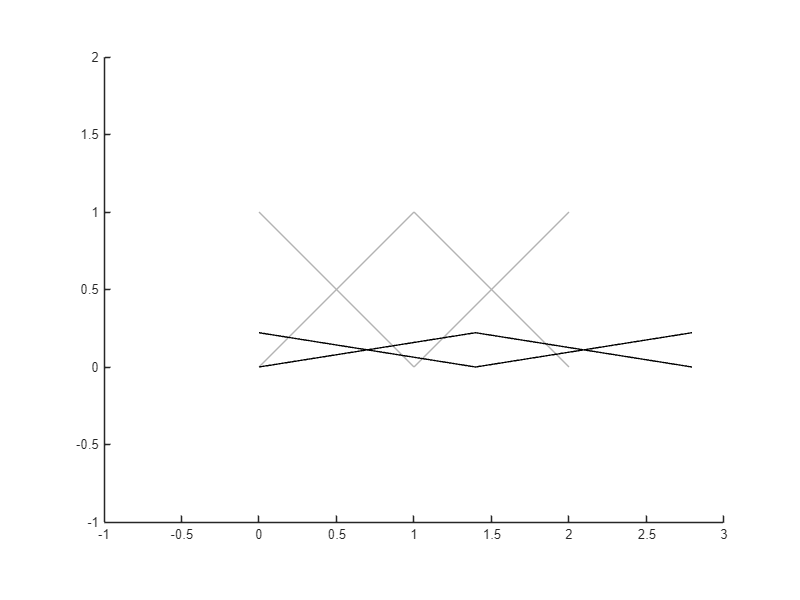

% Plot the deformed shape
plots.Plot_Deformed_Shape(squeeze(Uhis(end,:,:)),zeros(16,3));

Repeat the loading at the new configuration.

% Solve for the deformation history
Uhis_load=nr.Solve();

Loading Analysis StartIcrement = 1
    Iteration = 1, R = 3.750315e-02
    Iteration = 2, R = 2.487030e-03
    Iteration = 3, R = 6.664321e-04
    Iteration = 4, R = 7.022344e-06
    Iteration = 5, R = 3.762854e-08
Icrement = 2
    Iteration = 1, R = 4.099372e-02
    Iteration = 2, R = 2.355834e-03
    Iteration = 3, R = 8.658081e-04
    Iteration = 4, R = 1.568646e-05
    Iteration = 5, R = 5.654193e-08
Icrement = 3
    Iteration = 1, R = 4.466289e-02
    Iteration = 2, R = 2.180390e-03
    Iteration = 3, R = 1.265491e-03
    Iteration = 4, R = 3.069232e-05
    Iteration = 5, R = 1.340963e-07
Icrement = 4
    Iteration = 1, R = 4.891455e-02
    Iteration = 2, R = 2.074449e-03
    Iteration = 3, R = 1.415549e-03
    Iteration = 4, R = 5.674302e-05
    Iteration = 5, R = 2.808412e-07
Icrement = 5
    Iteration = 1, R = 5.217151e-02
    Iteration = 2, R = 2.017397e-03
    Iteration = 3, R = 2.822042e-03
    Iteration = 4, R = 9.947009e-05
    Iteration = 5, R = 2.957544e-06
    Iteration

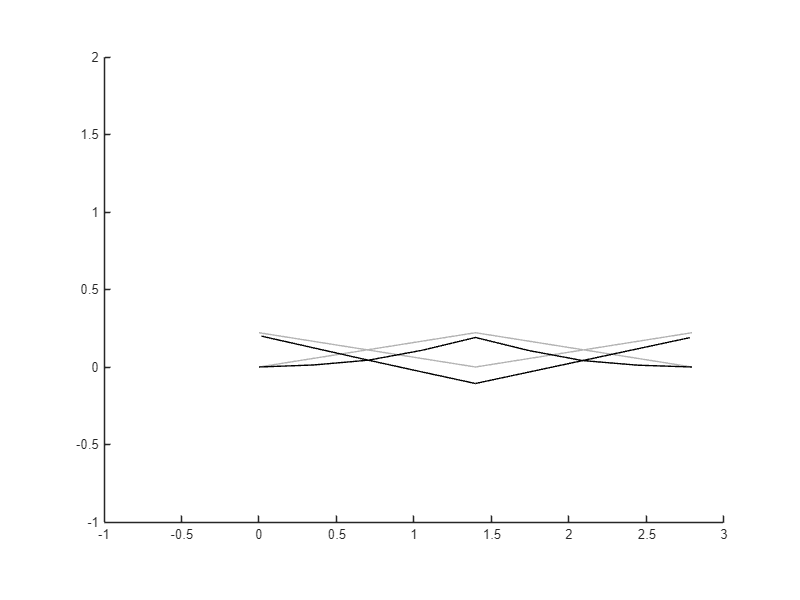

% Plot the deformed shape
plots.Plot_Deformed_Shape(squeeze(Uhis_load(end,:,:)),squeeze(Uhis(end,:,:)));

We can see that at the extended configuration, this system is having a much bigger deformation now! This is expected because the total structure height is now lower and the span is also larger. 

This example shows one nice thing about using the lumped parameter model formulations, we can easily capture the large kinematics shape morphing and the load-carrying performance of active structures. If these systems are modeled using 

#### **Practice Problems:**

To practice, please consider further working out the following problems. 

#### **Problem 01 **

Turn this system into a cantilever beam and see what happens. As the following figure: